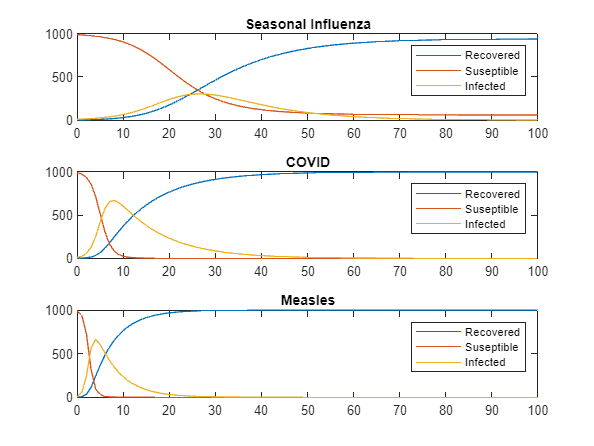

clear all;
clc;
% Initial Values
I0 = 10;
S0 = 990;
R0 = 0;

N = I0 + S0 + R0;
% Betai = .3; Gammai = .1;
% Betaii = 1; Gammaii = .1;
% Betaiii = 2; Gammaiii = .2;

Beta = [.3 1 2];
gamma = [.1 .1 .2];
ti = ["Seasonal Influenza","COVID","Measles"];
leg = ["Recovered","Suseptible","Infected"];

h = 1;
t0 = 0; tf = 100;
tiledlayout(3,1);

% Seasonal Inluenza
for j = 1:length(Beta)
    Gamma=gamma(j);
    BN1=Beta(j)/1000;
    
    time = t0:h:tf;
    Rvals = zeros(size(time));
    Svals = zeros(size(time));
    Ivals = zeros(size(time));
    Nvals = zeros(size(time));
    
    Rvals(1) = R0;
    Svals(1) = S0;
    Ivals(1) = I0;
    Nvals(1) = 1000;
    dRdt = @(I) Gamma*I;                  
    dSdt = @(I,S) -BN1*S*I;
    dIdt = @(I,S) (BN1*S*I)-(Gamma*I);
    % Seasonal Inluenza
        for i = 1:length(time)-1
            R=Rvals(i);
            S=Svals(i);
            I=Ivals(i);
            
            rk1 = dRdt(I);           % Runge Kutta Recovered K1 
            sk1 = dSdt(I,S);            % Runge Kutta Susceptible K1 
            ik1 = dIdt(I,S);           % Runge Kutta Infected K1
            
            ik2 = dIdt((I + ik1 * (h/2)) , S + sk1 * (h/2));           % Runge Kutta Infected K2
            rk2 = dRdt(I + ik1 * (h/2));           % Runge Kutta Recovered K2 
            sk2 = dSdt(I + ik1 * (h/2)  , (S + sk1 * (h/2)));           % Runge Kutta Susceptible K2
            
            sk3 = dSdt(I + ik2 * (h/2) ,(S + sk2 * (h/2)));            % Runge Kutta Susceptible K3 
            ik3 = dIdt((I + ik2 * (h/2)) ,S + sk2 * (h/2));           % Runge Kutta Infected K3
            rk3 = dRdt(I + ik2 * (h/2));           % Runge Kutta Recovered K3 
            
            ik4 = dIdt((I + ik3 * h),S + sk3 * h);           % Runge Kutta Infected K4
            sk4 = dSdt(I + ik3 * h , (S + sk3 * h));           % Runge Kutta Susceptible K4 
            rk4 = dRdt(I + ik3 * h);
            
            Rvals(i+1) = R + (1/6) * (rk1 + 2*(rk2) + 2*(rk3) + rk4) * h;
            Svals(i+1) = S + (1/6) * (sk1 + 2*(sk2) + 2*(sk3) + sk4) * h;
            Ivals(i+1) = I + (1/6) * (ik1 + 2*(ik2) + 2*(ik3) + ik4) * h;
            Nvals(i+1) = Rvals(i+1) + Svals(i+1) + Ivals(i+1);
        end
    nexttile;
    plot(time,Rvals);
    hold on;
    plot(time,Svals);
    plot(time,Ivals);
    title(ti(j));
    legend(leg);
    hold off;
    
    
end

parabolic

gamma = recovery rate

beta = infection rate